# Paper Movement Detection Using Correlation Coefficient.

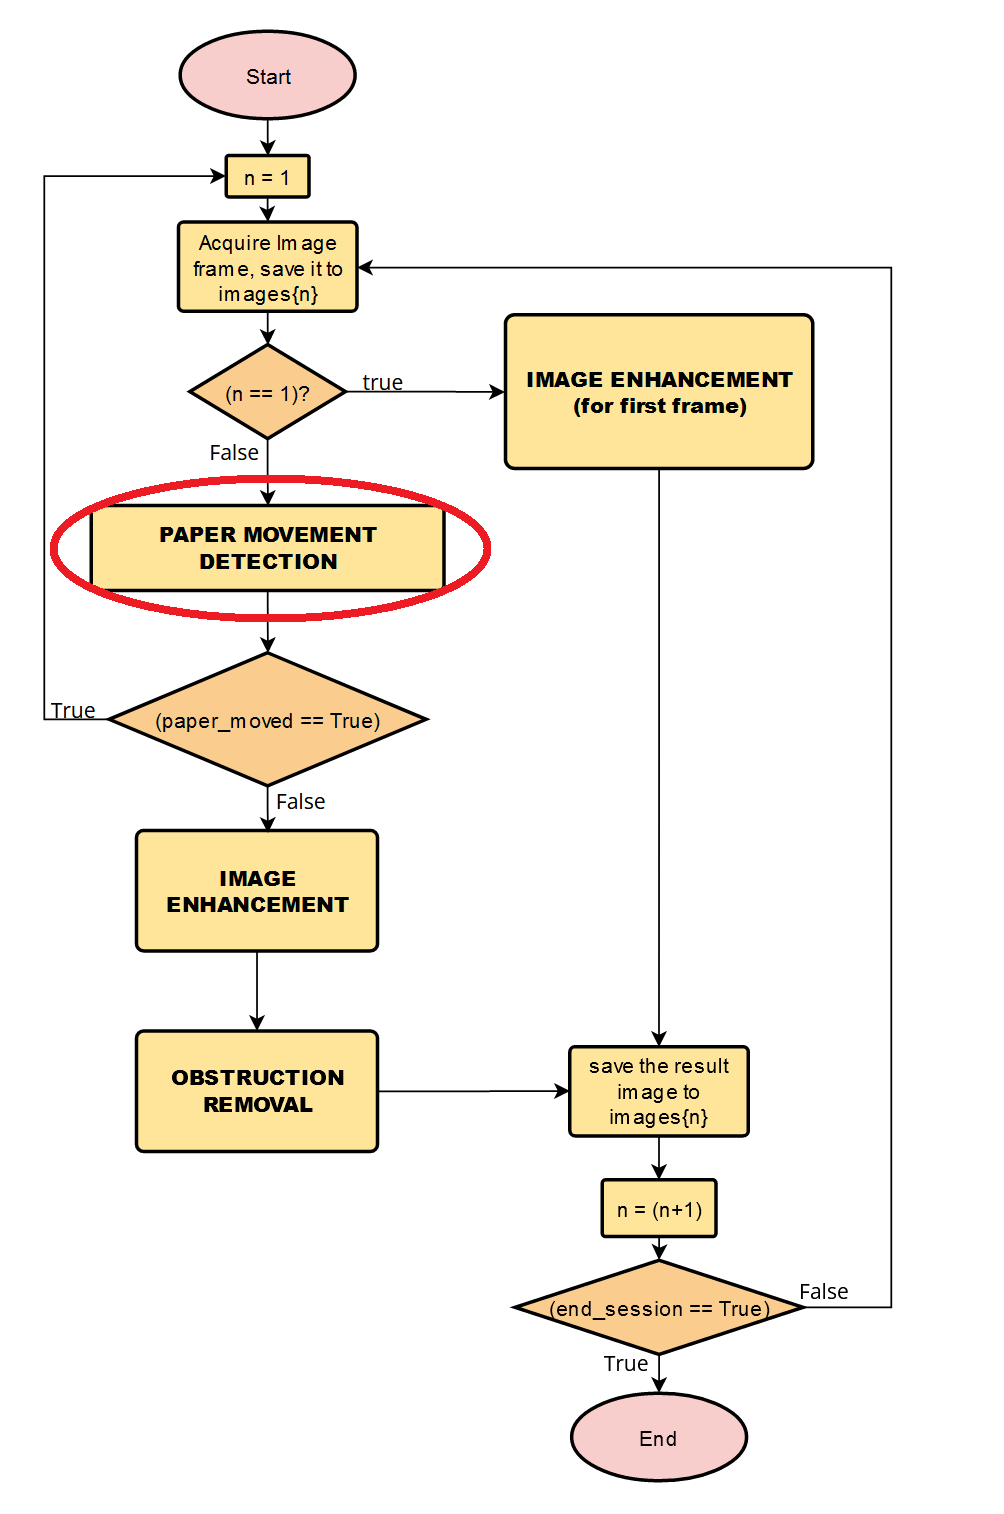

## METHODOLOGY ILLUSTRATION

The flowchart below shows basic information on the paper movement detection algorithm that we are going to explain here below:

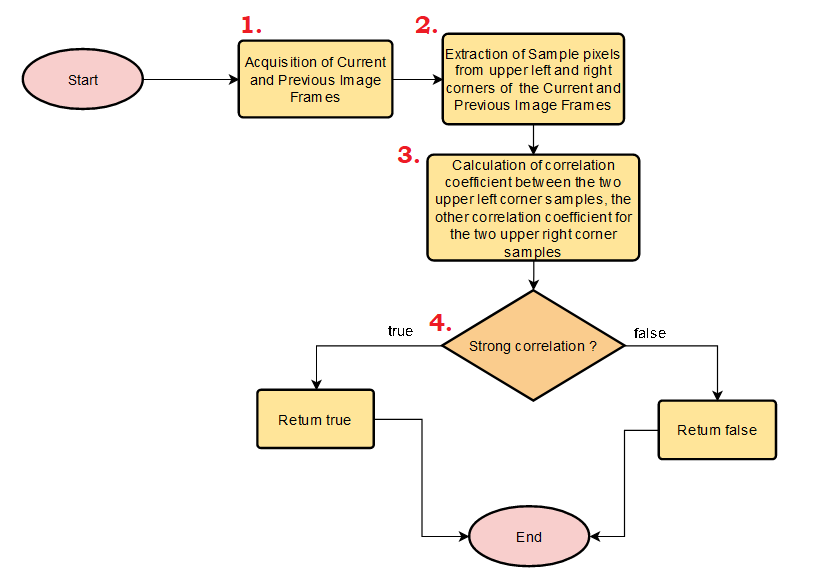

### STEP 1: CURRENT AND PREVIOUS IMAGES (FRAMES) ACQUISITION

 In this demonstration, we will assume two images, where one represents a paper positioned well, and other represents the paper moved a bit from its initial position. 

Here at Step 1, This process will acquire the current image frame and the previous image frame.  It will also trim the images, so as to show the white paper section at maximum.

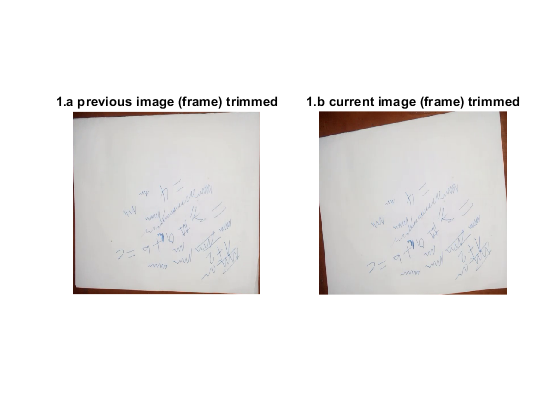

global cropFactor; global cam;
cropFactor=0.1;

% rawImage1=snapshot(cam);
rawImage1= imread("outImageCr1.png");
[rawImage1 rowCr1 rowCr2 colCr1 colCr2]=whitePaperTrimmer(rawImage1,cropFactor);
subplot(1,2,1)
imshow(rawImage1)
title("1.a previous image (frame) trimmed")

% rawImage2=snapshot(cam);
rawImage2=imread("outImageCr2.png");
rawImage2 = rawImage2(rowCr1:rowCr2,colCr1:colCr2,:);
subplot(1,2,2)
imshow(rawImage2)
title("1.b current image (frame) trimmed")

### STEP 2: SAMPLE PIXELS EXTRACTION FROM THE UPPER CORNERS OF THE TWO ACQUIRED IMAGES.

This process will take samples from the upper left and upper right corners of the two images.

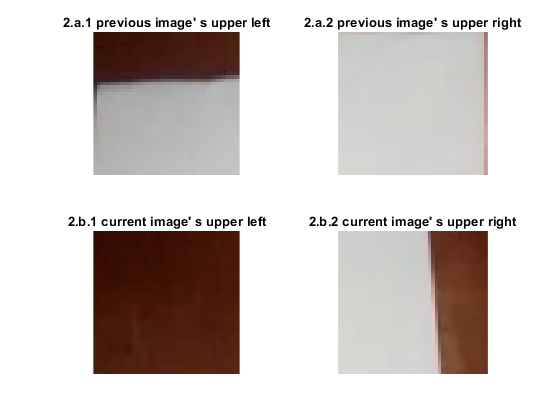

cropCornerArea=uint16(10); % area cropped from the corner, in percentage;
total_numberOfRows=rowCr2 - rowCr1 + 1;
total_numberOfColumns = colCr2 - colCr1 + 1;
farthest_row = total_numberOfRows * cropCornerArea / 100 ;
farthest_column = total_numberOfColumns * cropCornerArea / 100 ;
cropCorner1{1}=rawImage1(1:farthest_row,1:farthest_column,:);
cropCorner1{2}=rawImage1(1:farthest_row,end-farthest_column:end,:);
subplot(2,2,1)
imshow(cropCorner1{1})
title("2.a.1 previous image' s upper left")
subplot(2,2,2)
imshow(cropCorner1{2})
title("2.a.2 previous image' s upper right")

cropCorner2{1}=rawImage2(1:farthest_row,1:farthest_column,:);
cropCorner2{2}=rawImage2(1:farthest_row,end-farthest_column:end,:);
subplot(2,2,3)
imshow(cropCorner2{1})
title("2.b.1 current image' s upper left")
subplot(2,2,4)
imshow(cropCorner2{2})
title("2.b.2 current image' s upper right")

### STEP 3: CORRELATION COEFFICIENTS CALCULATIONS BETWEEN THE EQUIVALENT CORNERS OF THE TWO ACQUIRED IMAGES.

This process will equalize the taken samples, transform them into single column vectors, then compute two correlation coefficients: correlation coefficient between upper right corner of current image and the upper right corner of previous image, then correlation coefficient between upper left corner of current image and the upper left corner of previous image.

Corner1{1}=histeq(cropCorner1{1});
Corner1{2}=histeq(cropCorner1{2});
Corner2{1}=histeq(cropCorner2{1});
Corner2{2}=histeq(cropCorner2{2});

correlation_from_corner1=corr(double(Corner1{1}(:)),double(Corner2{1}(:)))

correlation_from_corner1 = 0.4252

correlation_from_corner2=corr(double(Corner1{2}(:)),double(Corner2{2}(:)))

correlation_from_corner2 = 0.6665

### STEP 4: RETURNING A RESULT OF A TEST FOR A HIGH CORRELATION COEFFICIENT

This process will decide and gives a true answer if each of the two correlation coefficients satisfies the threshold condition of being greater than 0.65.

Decision_ = ((correlation_from_corner1 > 0.65) && (correlation_from_corner2 > 0.65))

Decision_ = logical
   0
